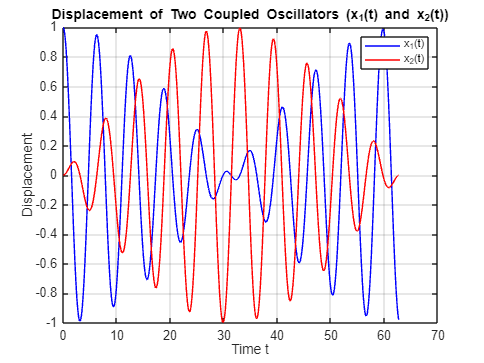

% I A a
omega = 1;
kappa = 0.1;

A = [0, 1, 0, 0;
    -omega^2, 0, kappa, 0;
     0, 0, 0, 1;
     kappa, 0, -omega^2, 0];

R0 = [1; 0; 0; 0];
t = linspace(0, 62.7, 1000);

x1_t = zeros(1, length(t));
x2_t = zeros(1, length(t));

for i = 1:length(t)
    R_t = expm(A * t(i)) * R0;
    x1_t(i) = R_t(1);
    x2_t(i) = R_t(3);
end

figure;
plot(t, x1_t, 'b', 'DisplayName', 'x_1(t)');
hold on;
plot(t, x2_t, 'r', 'DisplayName', 'x_2(t)');
xlabel('Time t');
ylabel('Displacement');
title('Displacement of Two Coupled Oscillators (x_1(t) and x_2(t))');
legend;
grid on;

% I A c
omega = 1;  
kappa = 0.1; 

A = [0 1 0 0;
     -omega^2 0 kappa 0;
     0 0 0 1;
     kappa 0 -omega^2 0];


[V, D] = eig(A);  

x0 = [1; 0; 0; 0];


c = V \ x0;  

t = linspace(0, 62.7, 1000);  


x1_t = zeros(size(t));
x2_t = zeros(size(t));


for i = 1:length(t)
 
    R_t = V * (c .* exp(diag(D) * t(i)));
    x1_t(i) = R_t(1);  
    x2_t(i) = R_t(3);  
end


figure;
plot(t, x1_t, 'b', 'LineWidth', 1.5);

hold on;
plot(t, x2_t, 'r', 'LineWidth', 1.5);

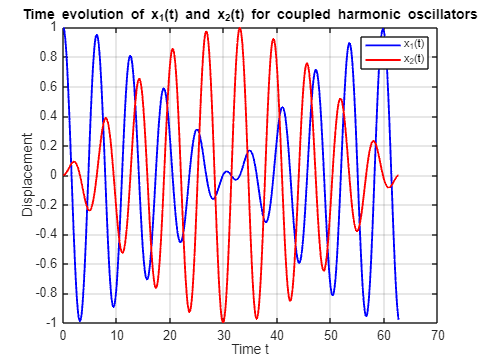

xlabel('Time t');
ylabel('Displacement');
title('Time evolution of x_1(t) and x_2(t) for coupled harmonic oscillators');
legend('x_1(t)', 'x_2(t)');
grid on;

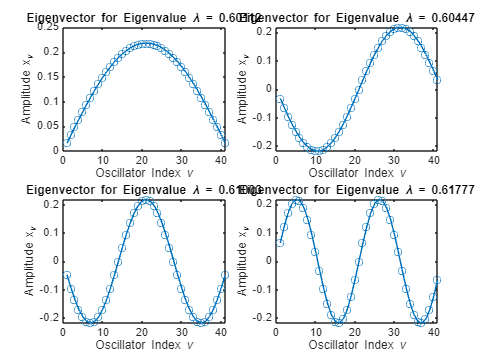

% I B b
N = 41;              
omega = 1;         
kappa = 0.2;         

M = zeros(N,N);
for i = 1:N
    M(i,i) = omega^2;        
    if i > 1
        M(i,i-1) = -kappa;   
    end
    if i < N
        M(i,i+1) = -kappa;  
    end
end

[eigenvectors, eigenvalues] = eig(M);
eigenvalues = diag(eigenvalues);
[eigenvalues_sorted, index] = sort(eigenvalues);

smallest_indices = index(1:4);
smallest_eigenvectors = eigenvectors(:, smallest_indices);

figure;
for i = 1:4
    subplot(2,2,i);
    plot(1:N, smallest_eigenvectors(:,i), '-o');
    title(['Eigenvector for Eigenvalue \lambda = ', num2str(eigenvalues_sorted(i))]);
    xlabel('Oscillator Index \nu');
    ylabel('Amplitude x_\nu');
end

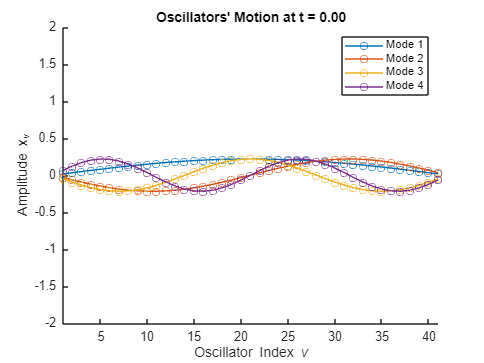

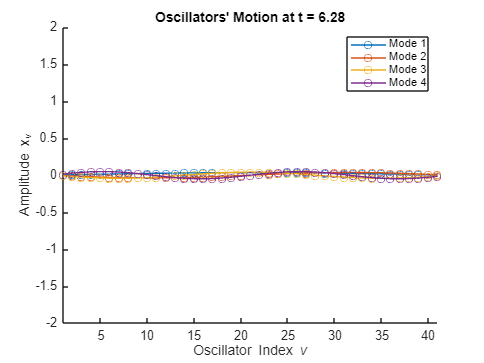

% I B b animation
N = 41;             
omega = 1;           
kappa = 0.2;         
T = 2*pi;            
t = linspace(0, T, 200); 

M = diag(omega^2 * ones(1, N)) + diag(-kappa * ones(1, N-1), 1) + diag(-kappa * ones(1, N-1), -1);
[eigenvectors, eigenvalues_matrix] = eig(M);
eigenvalues = diag(eigenvalues_matrix);

[eigenvalues_sorted, index] = sort(eigenvalues);
sorted_eigenvectors = eigenvectors(:, index);

figure;
axis([1 N -2 2]);
hold on;

for ti = 1:length(t)
    clf; 
    hold on;
    for i = 1:4
        mode_amplitude = sorted_eigenvectors(:, i) * cos(sqrt(eigenvalues_sorted(i)) * t(ti));
        plot(1:N, mode_amplitude, '-o', 'DisplayName', ['Mode ', num2str(i)]);
    end
    xlabel('Oscillator Index \nu');
    ylabel('Amplitude x_\nu');
    title(['Oscillators'' Motion at t = ', num2str(t(ti), '%.2f')]);
    axis([1 N -2 2]);
    legend('show');
    drawnow; 
end

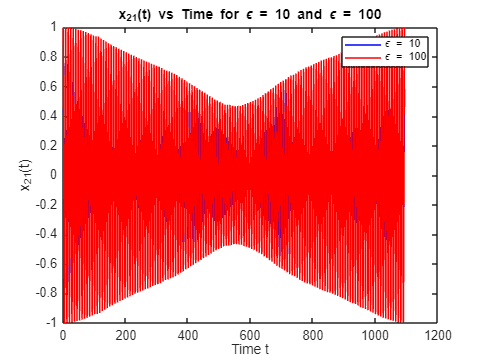

% I B d
N = 41;                   
omega = 1;                
kappa = 0.2;             
t_range = [0 1094];       
time_points = 10000;      
t = linspace(t_range(1), t_range(2), time_points);

M = diag(omega^2 * ones(1, N)) + diag(-kappa * ones(1, N-1), 1) + diag(-kappa * ones(1, N-1), -1);
[eigenvectors, eigenvalues_matrix] = eig(M);
eigenvalues = diag(eigenvalues_matrix);


[eigenvalues_sorted, index] = sort(eigenvalues);
sorted_eigenvectors = eigenvectors(:, index);


epsilon_values = [10, 100];
initial_conditions = zeros(N, length(epsilon_values));

for e = 1:length(epsilon_values)
    epsilon = epsilon_values(e);
    for nu = 1:N
        initial_conditions(nu, e) = exp(-(nu-21)^2 / epsilon);
    end
end


x_21_t = zeros(time_points, length(epsilon_values));


for e = 1:length(epsilon_values)
    c = sorted_eigenvectors' * initial_conditions(:, e); 
    for ti = 1:time_points
        x_t = sorted_eigenvectors * (c .* cos(sqrt(eigenvalues_sorted) * t(ti)));
        x_21_t(ti, e) = x_t(21);
    end
end

figure;
plot(t, x_21_t(:, 1), 'b', 'DisplayName', '\epsilon = 10');
hold on;
plot(t, x_21_t(:, 2), 'r', 'DisplayName', '\epsilon = 100');
xlabel('Time t');
ylabel('x_{21}(t)');
title('x_{21}(t) vs Time for \epsilon = 10 and \epsilon = 100');
legend('show');

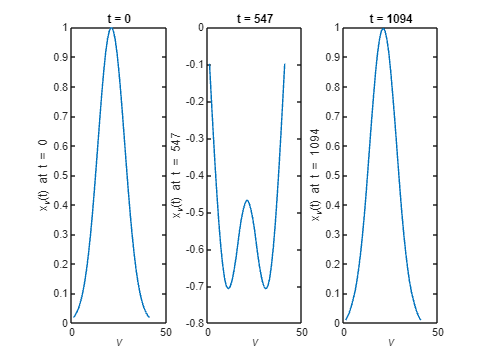



time_snapshots = [0, 547, 1094];
figure;
for i = 1:length(time_snapshots)
    ti = find(t >= time_snapshots(i), 1);
    x_t = sorted_eigenvectors * (c .* cos(sqrt(eigenvalues_sorted) * t(ti)));
    subplot(1, 3, i);
    plot(1:N, x_t);
    xlabel('\nu');
    ylabel(['x_\nu(t) at t = ', num2str(time_snapshots(i))]);
    title(['t = ', num2str(time_snapshots(i))]);
end

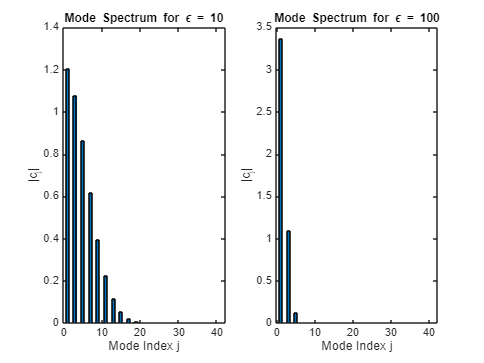

% I B e
c_values = zeros(N, length(epsilon_values));
for e = 1:length(epsilon_values)
    c_values(:, e) = sorted_eigenvectors' * initial_conditions(:, e);
end

figure;
for e = 1:length(epsilon_values)
    subplot(1, 2, e);
    bar(abs(c_values(:, e)));
    xlabel('Mode Index j');
    ylabel('|c_j|');
    title(['Mode Spectrum for \epsilon = ', num2str(epsilon_values(e))]);
end

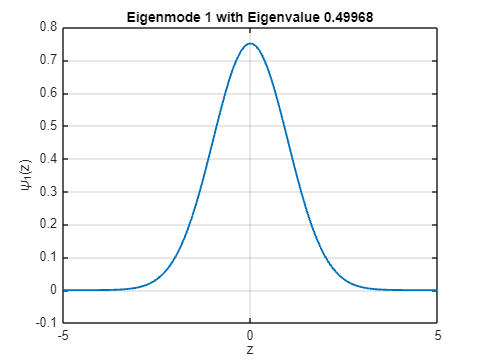

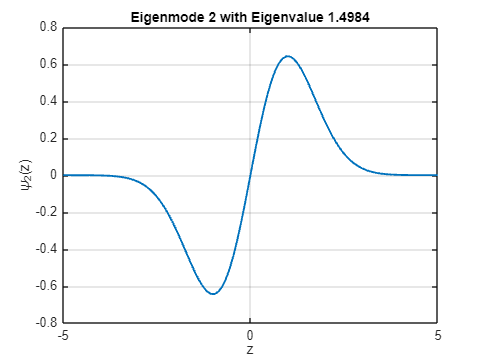

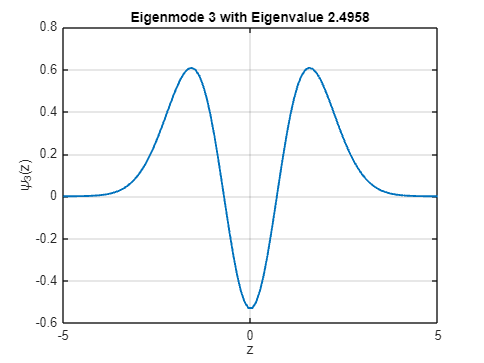

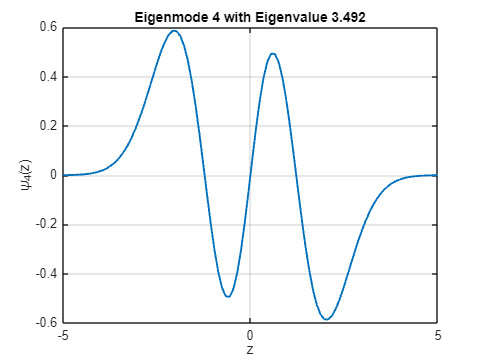

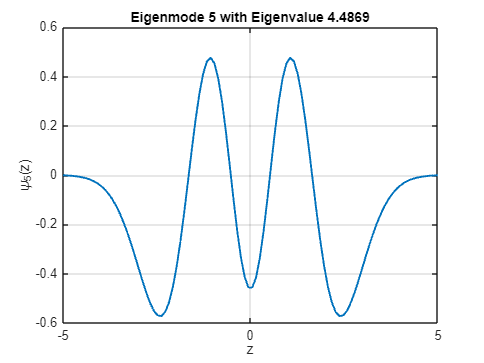

% II B b
N = 100;            
zmax = 10;           
hbar = 1;            
m = 1;              
omega = 1;          


dz = zmax / (N - 1); 
z = linspace(-zmax/2, zmax/2, N); 


V = 0.5 * m * omega^2 * z.^2; % V(z) = 1/2 * m * omega^2 * z^2

H = zeros(N); 

for i = 2:N-1
    H(i, i) = V(i) + hbar^2 / (m * dz^2); 
    H(i, i+1) = -hbar^2 / (2 * m * dz^2); 
    H(i, i-1) = -hbar^2 / (2 * m * dz^2); 
end


H(1,1) = V(1) + hbar^2 / (m * dz^2); 
H(N,N) = V(N) + hbar^2 / (m * dz^2); 

k = 5; 
[V, D] = eigs(H, k, 'smallestabs'); 


psi = V / sqrt(dz); 

% figure;
% for j = 1:k
%     subplot(k, 1, j);
%     plot(z, psi(:, j));
%     title(['Eigenmode ' num2str(j) ' with Eigenvalue ' num2str(D(j, j))]);
%     xlabel('z');
%     ylabel(['\psi_' num2str(j) '(z)']);
% end
% 
% fprintf('Normalization Check:\n');
% for j = 1:k
%     norm_value = sum(abs(psi(:, j)).^2) * dz;
%     fprintf('Mode %d: %f\n', j, norm_value);
% end

for j = 1:k
    figure;
    plot(z, psi(:, j), 'LineWidth', 1.5);
    title(['Eigenmode ' num2str(j) ' with Eigenvalue ' num2str(D(j, j))]);
    xlabel('z');
    ylabel(['\psi_' num2str(j) '(z)']);
    grid on;
end


fprintf(' Eigenmode |   Eigenvalue   | Normalization\n');

 Eigenmode |   Eigenvalue   | Normalization


fprintf('--------------------------------------------\n');

--------------------------------------------


for j = 1:k
    norm_value = sum(abs(psi(:, j)).^2) * dz;
    fprintf('    %d      |  %f  |  %f\n', j, D(j, j), norm_value);
end

    1      |  0.499681  |  1.000000
    2      |  1.498404  |  1.000000
    3      |  2.495848  |  1.000000
    4      |  3.492012  |  1.000000
    5      |  4.486901  |  1.000000


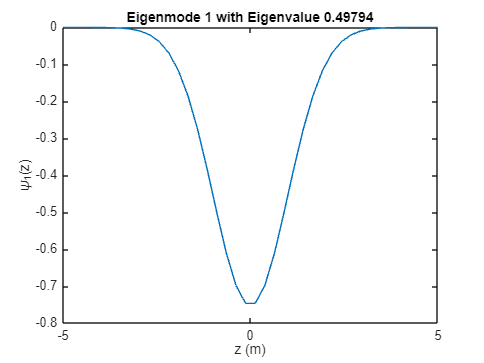

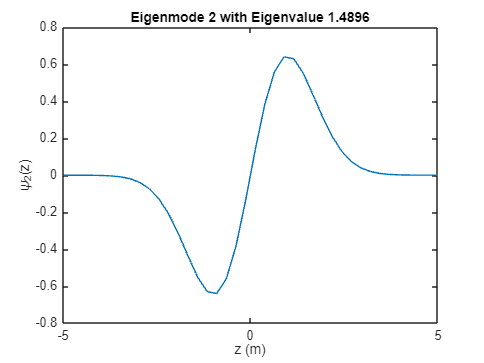

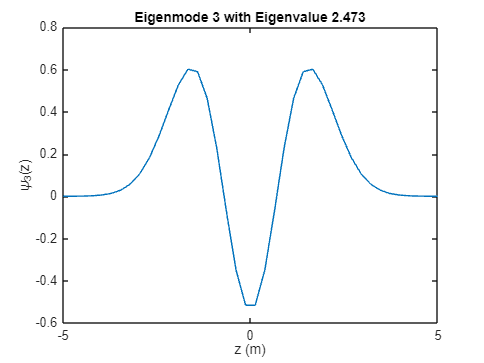

% II C b
z0 = 1; 
zmax = 10 * z0; 
N = 40; 
dz = zmax / (N - 1); 

z = linspace(-zmax/2, zmax/2, N)';

V = 0.5 * (z / z0).^2;

H = zeros(N, N);
for i = 1:N
    H(i, i) = V(i) + (z0 / dz)^2;
    if i > 1
        H(i, i-1) = -0.5 * (z0 / dz)^2;
        H(i-1, i) = -0.5 * (z0 / dz)^2;
    end
end

[eigenvectors, eigenvalues] = eig(H);

eigenvalues = diag(eigenvalues);

% Sort eigenvalues and corresponding eigenvectors
[eigenvalues, sortIdx] = sort(eigenvalues);
eigenvectors = eigenvectors(:, sortIdx);


for j = 1:N
    eigenvectors(:, j) = eigenvectors(:, j) / sqrt(sum(abs(eigenvectors(:, j)).^2) * dz);
end

for j = 1:3
    figure;
    plot(z, eigenvectors(:, j));
    xlabel('z (m)');
    ylabel(['\psi_' num2str(j) '(z)']);
    title(['Eigenmode ' num2str(j) ' with Eigenvalue ' num2str(eigenvalues(j))]);
end


table((1:N)', eigenvalues, 'VariableNames', {'Mode', 'Eigenvalue'})

ans = 40×2 table
    Mode    Eigenvalue
    ____    __________

      1      0.49794  
      2       1.4896  
      3        2.473  
      4       3.4478  
      5       4.4141  
      6       5.3716  
      7       6.3204  
      8       7.2604  
      9       8.1921  
     10       9.1174  
     11        10.04  
     12       10.967  
     13       11.909  
     14       12.874  
     15        13.87  
     16       14.899  



% II C c
n = 0:9;
analytic_eigenvalues = n + 0.5;

numerical_eigenvalues = eigenvalues(1:10);

comparison_table = table((0:9)', analytic_eigenvalues', numerical_eigenvalues, ...
    'VariableNames', {'n', 'Analytic_Eigenvalue', 'Numerical_Eigenvalue'})

comparison_table = 10×3 table
    n    Analytic_Eigenvalue    Numerical_Eigenvalue
    _    ___________________    ____________________

    0            0.5                  0.49794       
    1            1.5                   1.4896       
    2            2.5                    2.473       
    3            3.5                   3.4478       
    4            4.5                   4.4141       
    5            5.5                   5.3716       
    6            6.5                   6.3204       
    7            7.5                   7.2604       
    8            8.5                   8.1921       
    9            9.5                   9.1174       


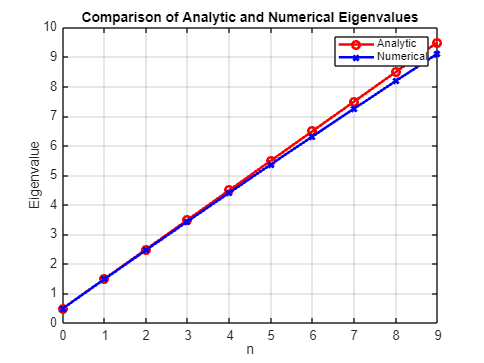


figure;
plot(0:9, analytic_eigenvalues, 'ro-', 'LineWidth', 2);
hold on;
plot(0:9, numerical_eigenvalues, 'bx-', 'LineWidth', 2);
xlabel('n');
ylabel('Eigenvalue');
legend('Analytic', 'Numerical');
title('Comparison of Analytic and Numerical Eigenvalues');
grid on;

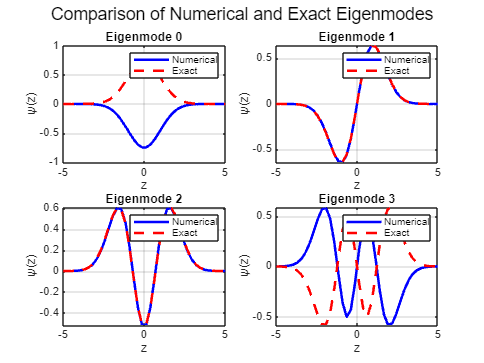


% II C d
figure;
for n = 1:4
    subplot(2, 2, n);
    plot(z, eigenvectors(:, n), 'b-', 'LineWidth', 2);
    hold on;

   
    psi_exact = hermiteH(n-1, z/z0) .* exp(-z.^2/(2*z0^2));
    psi_exact = psi_exact / sqrt(trapz(z, abs(psi_exact).^2)); % Normalization
    plot(z, psi_exact, 'r--', 'LineWidth', 2);
    
    title(['Eigenmode ', num2str(n-1)]);
    xlabel('z');
    ylabel('\psi(z)');
    legend('Numerical', 'Exact');
    grid on;
end
sgtitle('Comparison of Numerical and Exact Eigenmodes');

% II C e
z0 = 1;          
zmax = 10 * z0;      
N = 40;             
hbar = 1.0545718e-34; 
omega = 1;          


H = zeros(N, N);
dz = zmax / (N-1);  

for v = 1:N
    if v > 1
        H(v, v-1) = -0.5 * (z0 / dz)^2;
    end
    if v < N
        H(v, v+1) = -0.5 * (z0 / dz)^2;
    end
    H(v, v) = 0.5 * ((v-1) * dz / z0)^2 + (z0 / dz)^2;
end


[eigenvectors, D] = eig(H);
eigenvalues = diag(D);


exact_eigenvalues = hbar * omega * (0.5:1:(N-0.5))';


rj = (eigenvalues - exact_eigenvalues) ./ exact_eigenvalues;


table((0:N-1)', eigenvalues, exact_eigenvalues, rj, 'VariableNames', {'j', 'Numerical', 'Exact', 'rj'})

ans = 40×4 table
    j     Numerical      Exact           rj    
    __    _________    __________    __________

     0     1.2276      5.2729e-35    2.3281e+34
     1     3.0473      1.5819e-34    1.9264e+34
     2     4.8701      2.6364e-34    1.8472e+34
     3     6.6773       3.691e-34    1.8091e+34
     4      8.461      4.7456e-34    1.7829e+34
     5     10.217      5.8001e-34    1.7614e+34
     6     11.941      6.8547e-34     1.742e+34
     7     13.631      7.9093e-34    1.7234e+34
     8     15.285      8.9639e-34    1.7051e+34
     9     16.899      1.0018e-33    1.6868e+34
    10     18.472      1.1073e-33    1.6682e+34
    11     20.001      1.2128e-33    1.6492e+34
    12     21.482      1.3182e-33    1.6297e+34
    13     22.912      1.4237e-33    1.6094e+34
    14     24.287      1.5291e-33    1.5883e+34
    15     25.599      1.6346e

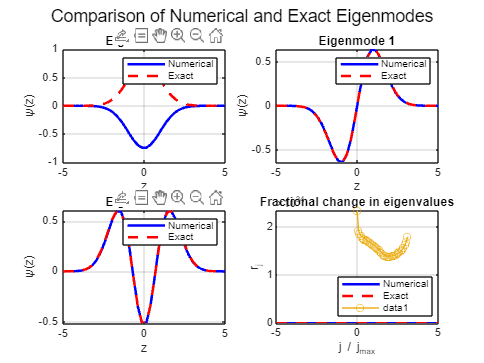


jmax = (zmax / (2 * sqrt(2) * z0))^2;
plot((0:N-1) / jmax, rj, '-o');
xlabel('j / j_{max}');
ylabel('r_j');
title('Fractional change in eigenvalues');

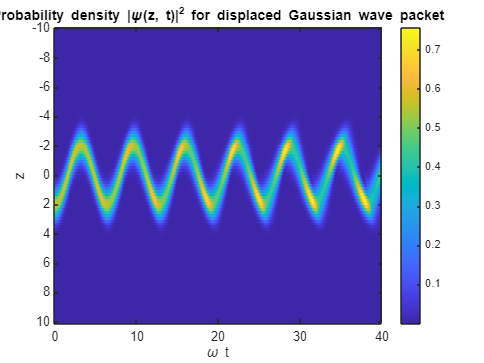

% II D a
z0 = 1;  
N = 100;   
zmax = 10 * z0; 
z = linspace(-zmax, zmax, N); 
dz = z(2) - z(1);  
omega = 1; 
tmax = 40;  
t = linspace(0, tmax, 1000); 


psi0 = exp(-(z - 2 * z0).^2 / (2 * z0^2));
N0 = 1 / sqrt(trapz(z, abs(psi0).^2));  
psi0 = N0 * psi0;  


H = zeros(N, N);
for n = 2:N-1
    H(n, n) = 1 / (dz^2) + 0.5 * (z(n) / z0)^2;
    H(n, n+1) = -0.5 / (dz^2);
    H(n, n-1) = -0.5 / (dz^2);
end
H(1, 1) = 1 / (dz^2) + 0.5 * (z(1) / z0)^2;
H(N, N) = 1 / (dz^2) + 0.5 * (z(N) / z0)^2;


[V, D] = eig(H);
eigenvalues = diag(D);  
eigenmodes = V;        


coefficients = eigenmodes' * psi0'; 


psi_t = zeros(N, length(t)); 
for k = 1:length(t)
    psi_k = zeros(N, 1);  
    for n = 1:N
        psi_k = psi_k + coefficients(n) * eigenmodes(:, n) * exp(-1i * eigenvalues(n) * t(k));
    end
    psi_t(:, k) = psi_k;
end


prob_density = abs(psi_t).^2;


figure;
imagesc(t, z, prob_density);
xlabel('\omega t');
ylabel('z');
title('Probability density |\psi(z, t)|^2 for displaced Gaussian wave packet');
colorbar;



% II D b
for k = 1:length(t)
    psi_k = zeros(N, 1);  
    for n = 1:N
        psi_k = psi_k + coefficients(n) * eigenmodes(:, n) * exp(-1i * eigenvalues(n) * t(k));
    end
    psi_t(:, k) = psi_k;

    expectation_z(k) = sum(conj(psi_t(:,k)) .* z' .* psi_t(:,k)) * dz;  % <z(t)>
end


scaled_expectation_z = expectation_z / z0;


exact_z = 2 * cos(omega * t);


figure;
plot(t, scaled_expectation_z, 'b', 'LineWidth', 2);

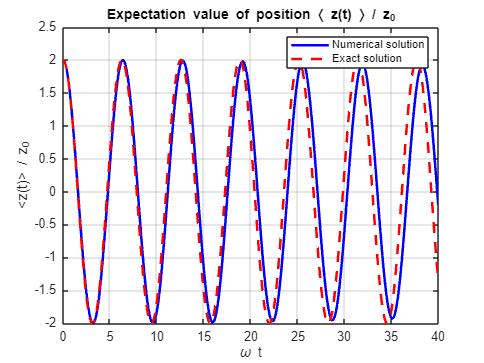

hold on;
plot(t, exact_z, 'r--', 'LineWidth', 2);
xlabel('\omega t');
ylabel('<z(t)> / z_0');
title('Expectation value of position \langle z(t) \rangle / z_0');
legend('Numerical solution', 'Exact solution');
grid on;



% H_anharmonic = zeros(N, N);
% for v = 1:N
%     if v > 1
%         H_anharmonic(v, v-1) = -0.5 * (z0 / dz)^2;
%     end
%     if v < N
%         H_anharmonic(v, v+1) = -0.5 * (z0 / dz)^2;
%     end
%     H_anharmonic(v, v) = 0.5 * ((z(v)/z0)^2 + 0.02 * (z(v)/z0)^4 + (z0/dz)^2);
% end
% 
% 
% [eigenvectors_anharmonic, D_anharmonic] = eig(H_anharmonic);
% eigenvalues_anharmonic = diag(D_anharmonic);
% 
% 
% psi_t_anharmonic = zeros(N, t_steps);
% expectation_z_anharmonic = zeros(1, t_steps);
% 
% for t = 1:t_steps
%     psi_t_anharmonic(:,t) = eigenvectors_anharmonic * (coefficients .* exp(-1i * eigenvalues_anharmonic * time(t) / hbar));
% 
%     expectation_z_anharmonic(t) = sum(conj(psi_t_anharmonic(:,t)) .* z' .* psi_t_anharmonic(:,t)) * dz;
% end
% 
% 
% figure;
% plot(time * omega, expectation_z_anharmonic / z0, 'b-', 'LineWidth', 1.5);
% xlabel('\omega t');
% ylabel('<z(t)>/z_0');
% title('Expectation Value of Position <z(t)>/z_0 with Anharmonic Potential');
% grid on;

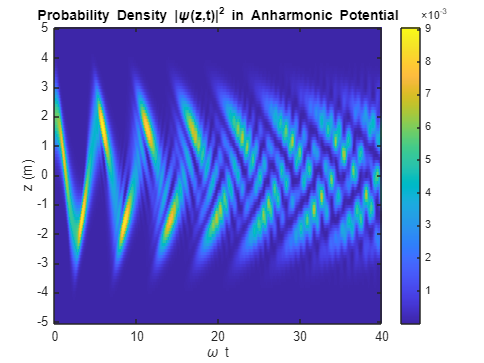

% II D c
z0 = 1; 
omega = 1; 
hbar = 1; 
m = 1; 


zmax = 10 * z0; 
N = 100; 
dz = zmax / (N-1);
z = linspace(-zmax/2, zmax/2, N)';


psi_0 = exp(-(z - 2*z0).^2 / (2 * z0^2));
psi_0 = psi_0 / sqrt(sum(psi_0.^2) * dz); 


V = 0.5 * (z/z0).^2 + 0.02 * (z/z0).^4;


T = -hbar^2 / (2 * m * dz^2) * (diag(ones(N-1,1),1) - 2 * diag(ones(N,1)) + diag(ones(N-1,1),-1));
H = T + diag(V);


[eigenvectors, eigenvalues_matrix] = eig(H);
eigenvalues = diag(eigenvalues_matrix);


c = eigenvectors' * (psi_0 * dz);


t_max = 40; 
nt = 1000; 
time = linspace(0, t_max, nt);


prob_density = zeros(N, nt);


for t_idx = 1:nt
    t = time(t_idx);
    psi_t = eigenvectors * (c .* exp(-1i * eigenvalues * t / hbar));
    prob_density(:, t_idx) = abs(psi_t).^2;
end

figure;
imagesc(time, z, prob_density);
xlabel('\omega t');
ylabel('z (m)');
title('Probability Density |\psi(z,t)|^2 in Anharmonic Potential');
colorbar;
axis xy;

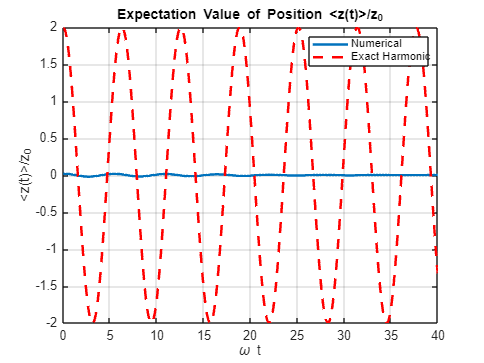



z_exp = sum(z .* prob_density * dz, 1);
figure;
plot(time, z_exp / z0, 'LineWidth', 2);
hold on;
plot(time, 2 * cos(omega * time), '--r', 'LineWidth', 2); 
xlabel('\omega t');
ylabel('<z(t)>/z_0');
title('Expectation Value of Position <z(t)>/z_0');
legend('Numerical', 'Exact Harmonic');
grid on;

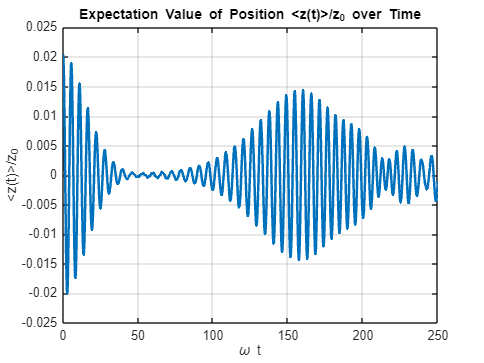



% II D d
t_max = 250; 
nt = 1000; 
time = linspace(0, t_max, nt);


z_exp = zeros(1, nt);


for t_idx = 1:nt
    t = time(t_idx);
    psi_t = eigenvectors * (c .* exp(-1i * eigenvalues * t / hbar));
    prob_density = abs(psi_t).^2;
    z_exp(t_idx) = sum(z .* prob_density * dz); 
end


figure;
plot(time, z_exp / z0, 'LineWidth', 2);
xlabel('\omega t');
ylabel('<z(t)>/z_0');
title('Expectation Value of Position <z(t)>/z_0 over Time');
grid on;

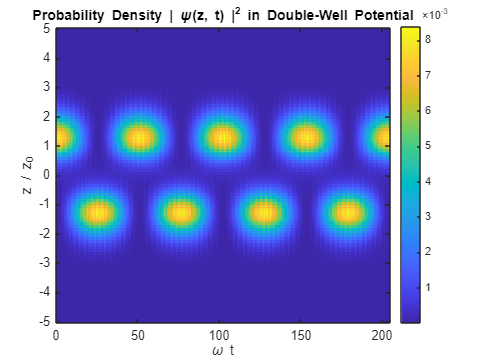

% II E a
z0 = 1; 
omega = 1; 
hbar = 1; 
m = 1; 


zmax = 10 * z0; 
N = 100; % change to 40 or 100
dz = zmax / (N-1); 
z = linspace(-zmax/2, zmax/2, N)'; 


psi_0 = exp(-(z - 1.3*z0).^2 / z0^2);
psi_0 = psi_0 / sqrt(sum(psi_0.^2) * dz); 


V = 0.5 * (z/z0).^2 + 4 * exp(-2 * z.^2 / z0^2);


T = -hbar^2 / (2 * m * dz^2) * (diag(ones(N-1,1),1) - 2 * diag(ones(N,1)) + diag(ones(N-1,1),-1));
H = T + diag(V);


[eigenvectors, eigenvalues_matrix] = eig(H);
eigenvalues = diag(eigenvalues_matrix);

c = eigenvectors' * (psi_0 * dz);

t_max = 204.6; 
nt = 1000; 
time = linspace(0, t_max, nt);


prob_density_evolution = zeros(N, nt);


for t_idx = 1:nt
    t = time(t_idx);
    psi_t = eigenvectors * (c .* exp(-1i * eigenvalues * t / hbar));
    prob_density_evolution(:, t_idx) = abs(psi_t).^2;
end


figure;
imagesc(time, z/z0 , prob_density_evolution); % z/z0
xlabel('\omega t');
ylabel('z / z_0');
title('Probability Density | \psi(z, t) |^2 in Double-Well Potential');
colorbar;
axis xy; 

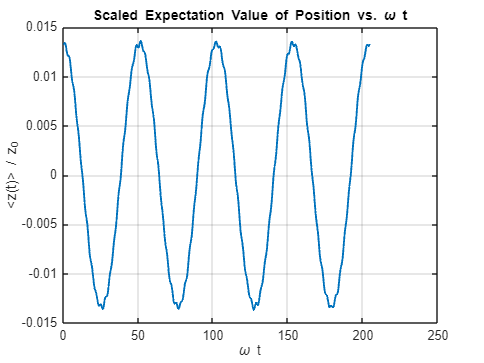




% II E b
expectation_z = zeros(1, nt);


for t_idx = 1:nt
    t = time(t_idx);
    psi_t = eigenvectors * (c .* exp(-1i * eigenvalues * t / hbar));
    expectation_z(t_idx) = real(psi_t' * (z .* psi_t) * dz); 
end

scaled_expectation_z = expectation_z / z0;


figure;
plot(time, scaled_expectation_z, 'LineWidth', 1.5);
xlabel('\omega t');
ylabel('<z(t)> / z_0');
title('Scaled Expectation Value of Position vs. \omega t');
grid on;



[maxima, max_locs] = findpeaks(scaled_expectation_z, time);
tunneling_period = max_locs(2) - max_locs(1); 
disp(['Tunneling Period: ', num2str(tunneling_period), ' (in units of \omega t)']);

Tunneling Period: 23.9622 (in units of \omega t)




delta_E = abs(eigenvalues(2) - eigenvalues(1));
expected_tunneling_period = 2 * pi * hbar / delta_E;
disp(['Expected Tunneling Period: ', num2str(expected_tunneling_period), ' (in units of \omega t)']);

Expected Tunneling Period: 51.1554 (in units of \omega t)
